# Visualize Wuhan Coronavirus / Covid-19 Cases updated from Channel New Asia

From [https://www.channelnewsasia.com/news/topics/wuhan-virus,](https://www.channelnewsasia.com/news/topics/wuhan-virus,) extract wuhan/covid-19 virus data (table, chart and Singapore Report).

Links :

1) [https://spreadsheets.google.com/feeds/list/1lwnfa-GlNRykWBL5y7tWpLxDoCfs8BvzWxFjeOZ1YJk/1/public/values?alt=json](https://spreadsheets.google.com/feeds/list/1lwnfa-GlNRykWBL5y7tWpLxDoCfs8BvzWxFjeOZ1YJk/1/public/values?alt=json)

2) [https://spreadsheets.google.com/feeds/list/1NbedmkD3VpoP6Poc_1Xl-ElroXi08X5UyNBeyI1ts28/1/public/values?alt=json](https://spreadsheets.google.com/feeds/list/1NbedmkD3VpoP6Poc_1Xl-ElroXi08X5UyNBeyI1ts28/1/public/values?alt=json) (Not updated except China)

3)[ https://spreadsheets.google.com/feeds/list/1lwnfa-GlNRykWBL5y7tWpLxDoCfs8BvzWxFjeOZ1YJk/2/public/values?alt=json](https://spreadsheets.google.com/feeds/list/1lwnfa-GlNRykWBL5y7tWpLxDoCfs8BvzWxFjeOZ1YJk/2/public/values?alt=json)

# Automate data extraction and structuring of data into Table in one function/one line of code.

It will use helper function defined at covid19data.m to extract the data from Channel News Asia and structure data to table format. The output of function contains 4 tables which are

1) The latest confirmed and death cases 

2) The timeline of confirmed cases 

3) The timeline of death cases 

4) The latest report of Singapore

you may reuse the function in other MATLAB's script as long as covid19data.m is in your working path

[table_overall_a,table_overall_b_Case,table_overall_b_Death,table_singapore] = covid19data;

# Visualize the Table Form Data 

 table_overall_a=sortrows(table_overall_a,"Case",'descend')

table_overall_a = 204×4 table
        Country                  Updated               Case     Death
    ________________    __________________________    ______    _____

    "United States"     "2020-03-30T17:36:34.995Z"    143532     2572
    "Italy"             "2020-03-30T17:36:34.995Z"    101739    11591
    "Spain"             "2020-03-30T17:36:34.995Z"     85195     7340
    "China"             "2020-03-30T17:36:34.995Z"     81470     3304
    "Germany "          "2020-03-30T17:36:34.995Z"     63929      560
    "Iran"              "2020-03-30T17:36:34.995Z"     41495     2757
    "France "           "2020-03-30T17:36:34.995Z"     40174     2606
    "United Kingdom"    "2020-03-30T17:36:34.995Z"     22141     1408
    "Switzerland"       "2020-03-30T17:36:34.995Z"     15526      333
    "Belgium "          "2020-03-30T17:36:34.995Z"     11899   

# Visualize the Timeline Chart Form Data 

#### Figure 1 : StackedPlot of Covid-19 Virus Confirmed Cases 

(Not working as Channel News Asia didn't update the timeline for other countries except china, I will try to look for other sources)

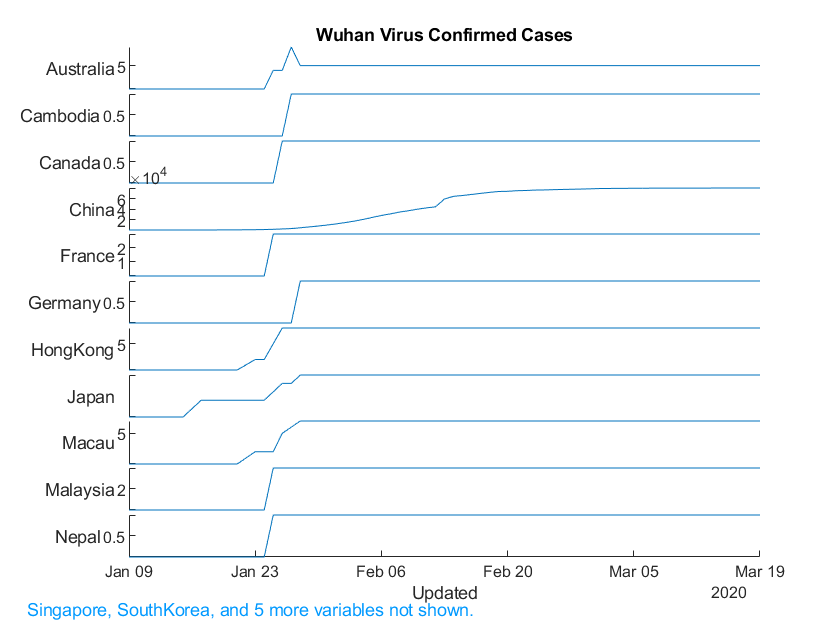

figure()
stackedplot(table2timetable(table_overall_b_Case));
title("Wuhan Virus Confirmed Cases")

#### Figure 2 : StackedPlot of Covid-19 Virus Death Cases

(Not working as Channel News Asia didn't update the timeline for other countries except china, I will try to look for other sources)

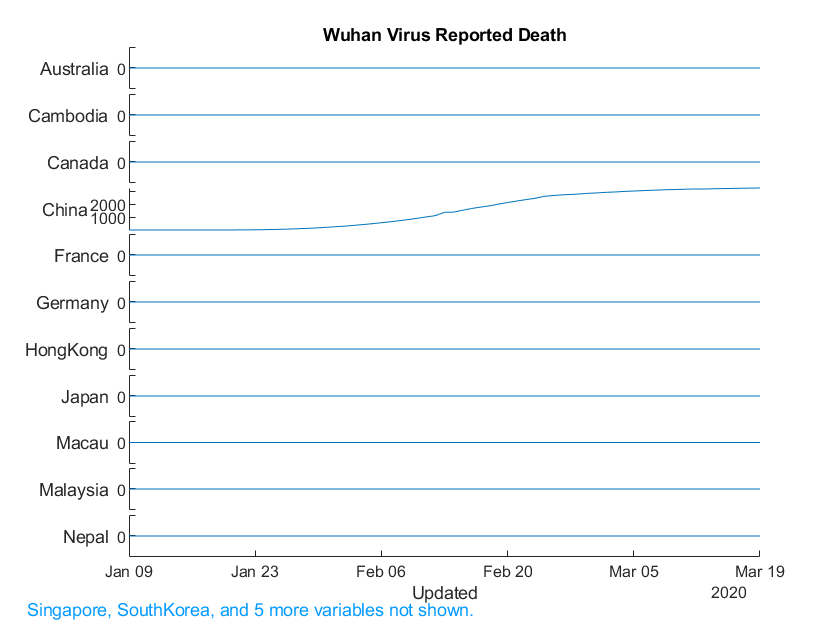

figure()
stackedplot(table2timetable(table_overall_b_Death));
title("Wuhan Virus Reported Death")

#### Figure 3 :  Confirmed Cases & Reported Death in China

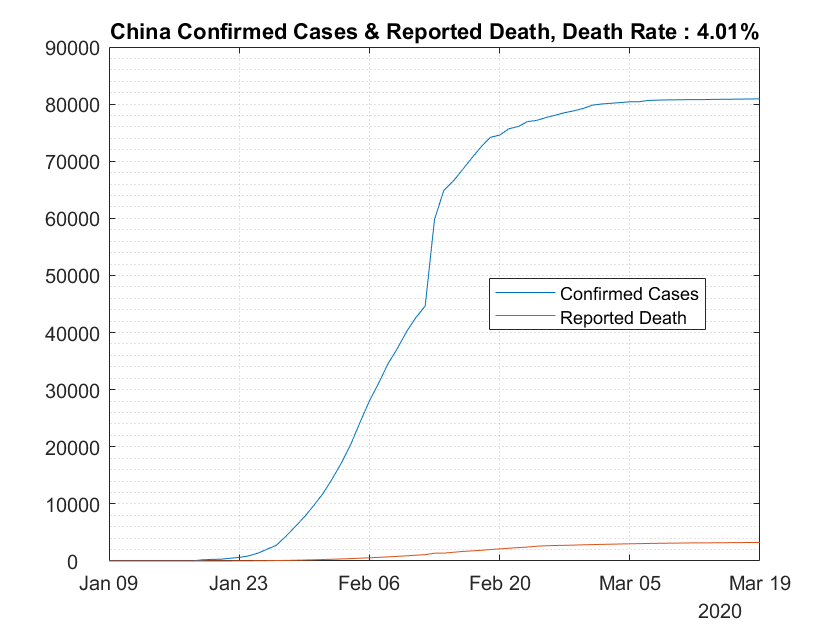

figure()
plot(table_overall_b_Case.Updated,table_overall_b_Case{:,"China"})
hold on
plot(table_overall_b_Death.Updated,table_overall_b_Death{:,"China"})
grid('minor')
legend('Confirmed Cases','Reported Death','Location','best')
title(sprintf("China Confirmed Cases & Reported Death, Death Rate : %0.2f%%",table_overall_b_Death{end,"China"}/table_overall_b_Case{end,"China"}*100))
Yvalues = get(gca,'YTick');
set(gca,'YTickLabel',Yvalues); 
hold off

#### Figure 4 : New Confirmed Cases in China

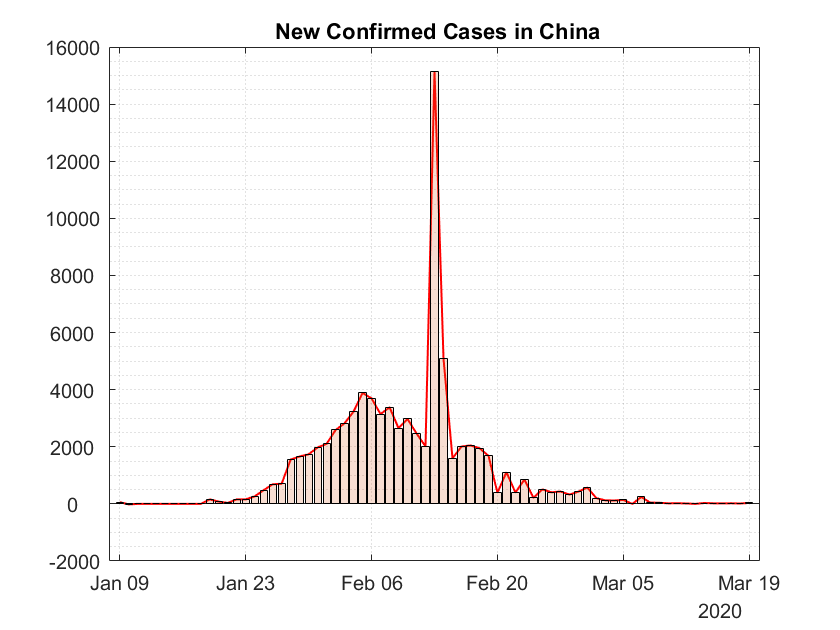

figure()
plot([table_overall_b_Case.Updated(1);table_overall_b_Case.Updated(2:end)],...
    [table_overall_b_Case{:,"China"}(1);diff(table_overall_b_Case{:,"China"})],'r','LineWidth',1)
hold on
k=bar([table_overall_b_Case.Updated(1);table_overall_b_Case.Updated(2:end)],...
    [table_overall_b_Case{:,"China"}(1);diff(table_overall_b_Case{:,"China"})]);
k.FaceAlpha = 0.2;
grid('minor')
title(" New Confirmed Cases in China");
Yvalues = get(gca,'YTick');
set(gca,'YTickLabel',Yvalues); 
hold off

#### Figure 5 : (Other than China) Confirmed Cases in Other Countries

(Not working as Channel News Asia didn't update the timeline for other countries except china, I will try to look for other sources)

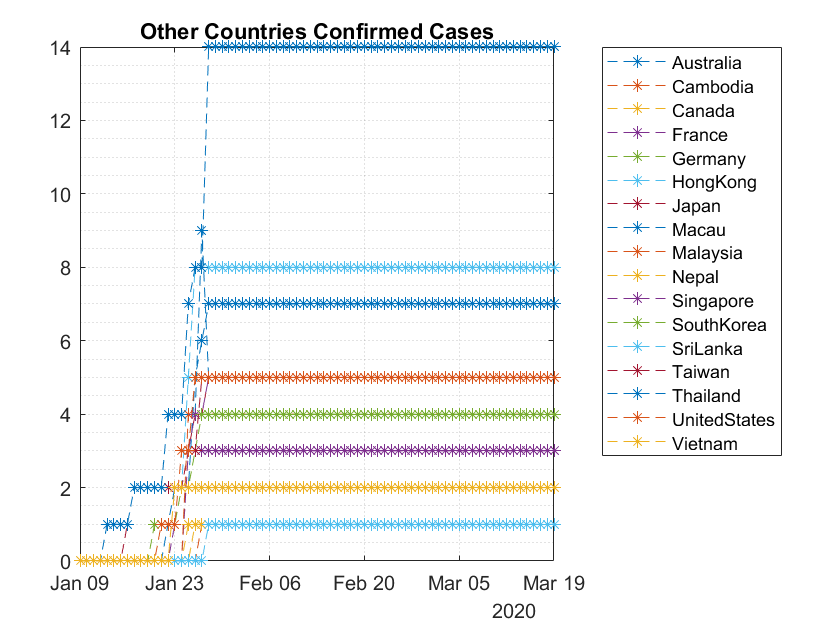

figure()
variableName = table_overall_b_Case.Properties.VariableNames;
variableName(strcmp(variableName,'China'))=[];
plotother = table_overall_b_Case;
plotother.China = [];
plot(table_overall_b_Case.Updated,plotother{:,2:end},'--*')
grid('minor')
legend(variableName(2:end),"Location","bestoutside")
title("Other Countries Confirmed Cases")
hold off

#### Figure 6 : Visualization of Geo Bubble Mapping

Get the latitude and longitude of countries from [https://developers.google.com/public-data/docs/canonical/countries_csv](https://developers.google.com/public-data/docs/canonical/countries_csv)

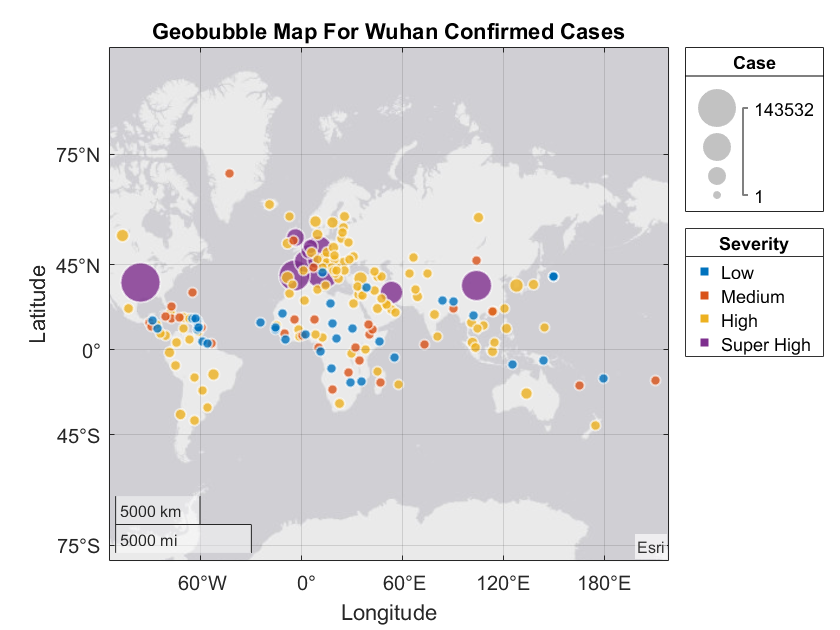

table_location = readtable('Geolocation.xlsx');
for i=1:1:height(table_overall_a)
    index=find(strcmp(strtrim(table_overall_a.Country(i)),strtrim(table_location.name)));
    if ~isempty(index)
        latitude(i) = table_location.latitude(index);
        longitude(i) = table_location.longitude(index);
    else
        latitude(i) = 40; %cruiseship
        longitude(i) = 150; %cruiseship
    end
end
geotable = table(latitude',longitude',table_overall_a.Case);
geotable.Properties.VariableNames = {'latitude' 'longitude' 'Case'};
figure()
gb = geobubble(geotable,'latitude','longitude','SizeVariable','Case','Title','Geobubble Map For Wuhan Confirmed Cases');
gb.SourceTable.Severity = discretize(table_overall_a.Case,[0 10 50 10000 200000],...
                                     'categorical', {'Low', 'Medium', 'High', 'Super High'});
gb.ColorVariable = 'Severity';

## Singapore Latest Covid-19 Report

table_singapore

table_singapore = 6×1 table
                              Singapore
                              _________

    Date                      "Mar 30" 
    New cases announced       "35"     
    Confirmed cases so far    "879"    
    Recovered                 "228"    
    Still in hospital         "3"      
    Deaths                    "420"    
